Adaptive Thresholdig

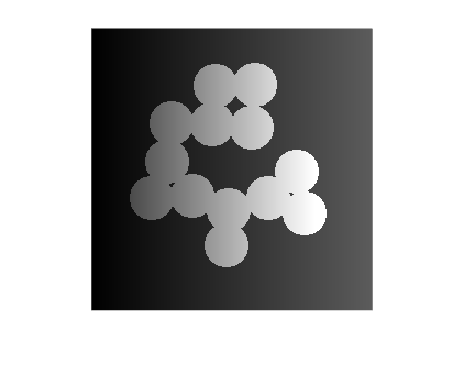

adaptive = imread("adaptivebk.tif");
figure;
imshow(adaptive);

Divide

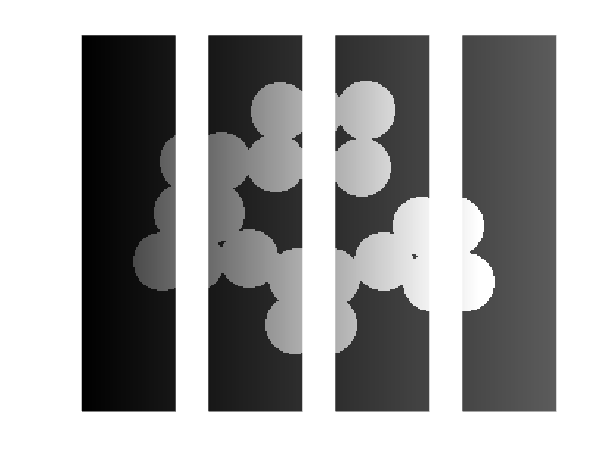

p1 = adaptive(:,1:64);
p2 = adaptive(:,65:128);
p3 = adaptive(:,129:192);
p4 = adaptive(:,193:256);

figure;
subplot(1,4,1);
imshow(p1);
subplot(1,4,2);
imshow(p2);
subplot(1,4,3);
imshow(p3);
subplot(1,4,4);
imshow(p4);


% imshow([p1 p2 p3 p4]);

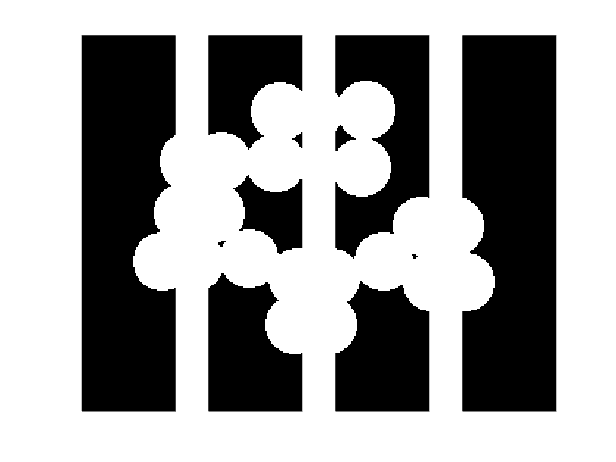

cam = imread('cameraman.tif');
t = graythresh(cam);

g1 = im2bw(p1,graythresh(p1));
g2 = im2bw(p2,graythresh(p2));
g3 = im2bw(p3,graythresh(p3));
g4 = im2bw(p4,graythresh(p4));

figure;
subplot(1,4,1);
imshow(g1);
subplot(1,4,2);
imshow(g2);
subplot(1,4,3);
imshow(g3);
subplot(1,4,4);
imshow(g4);


% imshow([g1 g2 g3 g4]);

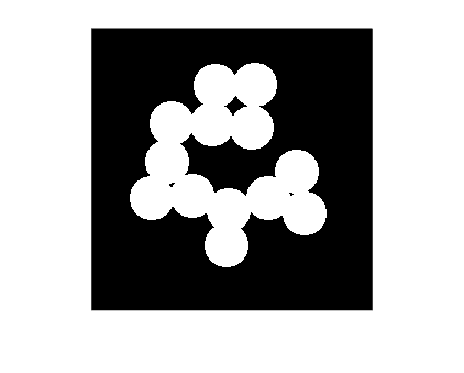

joint_bw = [g1 g2 g3 g4];
figure;
imshow(joint_bw);

Image Segmentation : Edge Detection

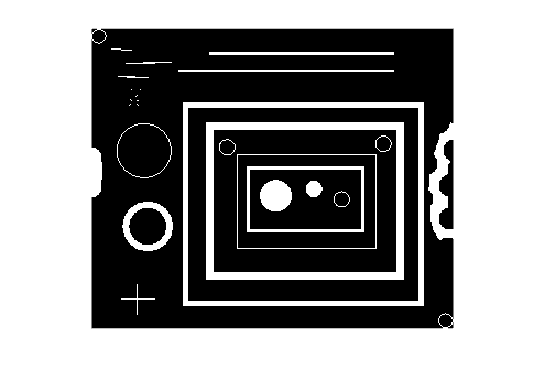

blobs = imread('blobs.png');
imshow(blobs);

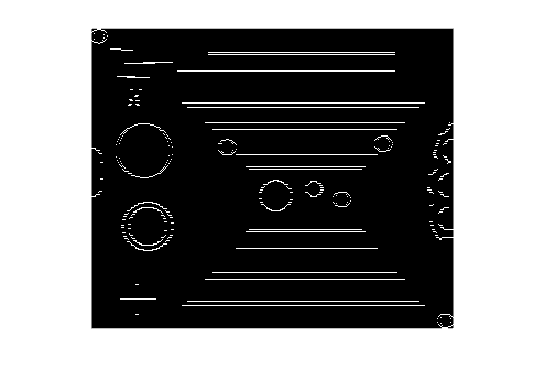


filter_h = [-1 -1 -1;2 2 2;-1 -1 -1];
filter_v = [-1 2 -1;-1 2 -1;-1 2 -1];
blobs_filter_h = filter2(filter_h,blobs);
blobs_filter_v = filter2(filter_v,blobs);
imshow(blobs_filter_h);

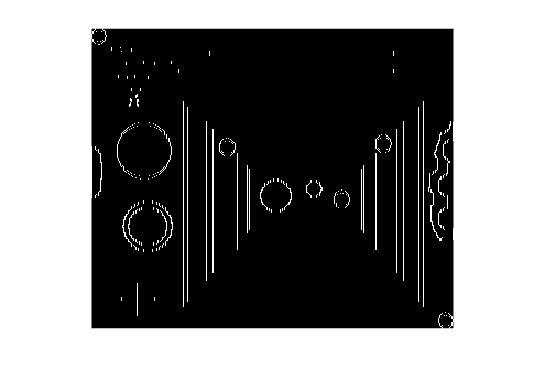

imshow(blobs_filter_v);